# RETO

Carlos Colchero Leal                                     A00835489

Rodrigo Leal Torres                                       A00836930

Héctor Ali Sandoval Sandoval Dávila            A01722672

Raúl Correa Ocañas                                     A01722401

Kristina de la Rosa                                        A01198427

Correr documento desde el principio, aplicar *clc* y *clear* para evitar bugs y errores inexplicables.

clc
clear

## 1.- BIOT-SAVART: de Emisor a Receptor

- 
$$r:=\textrm{Radio}\;\textrm{del}\;\textrm{solenoide}\;\textrm{emisor},$$


- 
$$N:=\textrm{Numero}\;\textrm{de}\;\textrm{vueltas}\;\textrm{del}\;\textrm{emisor},$$


- 
$$x:=\textrm{Distancia}\;\textrm{entre}\;\textrm{solenoides}\;\textrm{emisor}\;y\;\textrm{receptor},$$


- 
$$\mu_0 :=\textrm{Permeabilidad}\;\textrm{del}\;\textrm{vacío}=4\pi *{10}^{-7} \;{\textrm{Hm}}^{-1} ,$$


- 
$$I\left(t\right):=\textrm{Corriente}\;\textrm{del}\;\textrm{solenoide}\;\textrm{emisor}\ldotp$$


R_emisor =0.025; % RADIO del emisor (metros)
N_emisor =12; % NUMERO DE VUELTAS
x =0.1; % DISTANCIA DE SOLENOIDE A SOLENOIDE
mu_0 = 4*pi * 10^-7; % PERMEABILIDAD DEL VACÍO


$$I\left(t\right)=\mathrm{Amplitud}*\cos \left(\frac{2\pi }{\mathrm{periodo}}t\right)$$


syms t;
% SEGUNDOS, Periodo de la corriente
periodo = 85.6 * 10^-9;
amplitud = 0.0171 * 10^-3; 
I_emisor = amplitud*cos(2*pi*t / periodo);


$$\left\|\vec{B_x } \left(t\right)\right\|=N\frac{\mu_0 {I\left(t\right)r}^2 }{2{\left(r^2 +x^2 \right)}^{3/2} }$$


% Subestestimacion de campo (caso "real")
B_inductor = (mu_0*I_emisor*R_emisor^2*N_emisor)/(2*(R_emisor^2 + x^2)^(3/2)); 

## 2.- FARADAY: EMF en Receptor

- 
$$\phi_m :=\textrm{Flujo}\;\textrm{magnético},$$


- 
$$A:=\textrm{área}\;\textrm{donde}\;\textrm{fluye}\;\textrm{el}\;\textrm{campo}\;\textrm{magnético}=\pi r^2 ,$$


- 
$$r:=\textrm{radio}\;\textrm{del}\;\textrm{receptor},$$


- 
$$\varepsilon :=\textrm{Fuerza}\;\textrm{electromotriz},$$


R_receptor =0.04; % RADIO del receptor (metros)
A = pi*R_receptor^2; % AREA del receptor (m^2)

N_receptor =24;


$$\phi_m =\int \vec{B} \cdot d\vec{a} =B*A$$


phi = B_inductor * A; % CAMPO MAGNÉTICO * AREA del receptor (COS(0))


$$\varepsilon =-N\frac{d\phi_m }{\textrm{dt}}$$


dphidt = diff(phi);
epsilon = -N_receptor*dphidt;

## 3.- REGLA DE OHM: Corriente inducida en Receptor

ohm =175; % RESISTENCIA EN EL SEGUNDO SOLENOIDE
I_inducido = epsilon/ohm; % CORRIENTE INDUCIDA

## 4.- LEY DE AMPERE: Campo magnético inducido del Receptor


$$\left\|\vec{B_x } \left(t\right)\right\|=N\frac{\mu_0 I\left(t\right)}{2r}$$


B_inducido = N_receptor*mu_0*I_inducido/(2*R_receptor);

## 5.- PARAMETRIZACIÓN

dt = periodo/10;
t_plot = 0:dt:periodo*4;
marker = "O";
lw = 2;

## 6.- RENDER DE CORRIENTES

figure(1)
subplot(2,2,1)
a1 = plot(t_plot,subs(I_emisor,t,t_plot),"Marker",marker,"LineWidth",lw,"Color","red");
legend(a1,"I Inductora");
xlabel("Tiempo (segundos)")
ylabel("I Inductora (amperios)") 
title("I Inductora contra Tiempo")

subplot(2,2,2)
a2 = plot(t_plot,subs(I_inducido,t,t_plot),"Marker",marker,"LineWidth",lw,"Color","red");
legend(a2,"I Inducida")
xlabel("Tiempo (segundos)")
ylabel("I Inducida (amperios)") 
title("I Inducida contra Tiempo")

## 7.- RENDER DE CAMPOS MAGNETICOS

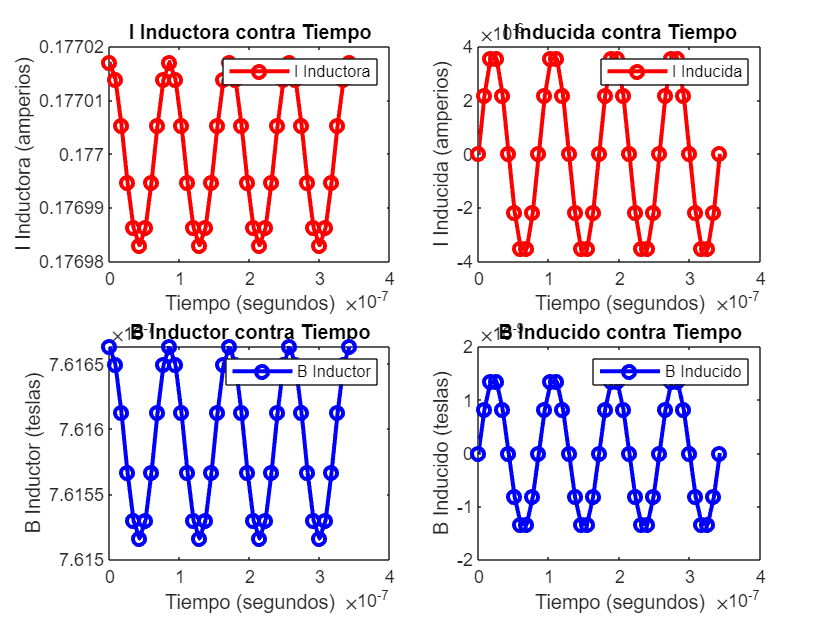

subplot(2,2,3)
a3 = plot(t_plot,subs(B_inductor,t,t_plot),"Marker",marker,"LineWidth",lw,"Color","blue");
legend(a3,"B Inductor")
xlabel("Tiempo (segundos)")
ylabel("B Inductor (teslas)") 
title("B Inductor contra Tiempo")
subplot(2,2,4)
a3 = plot(t_plot,subs(B_inducido,t,t_plot),"Marker",marker,"LineWidth",lw,"Color","blue");
legend(a3,"B Inducido")
xlabel("Tiempo (segundos)")
ylabel("B Inducido (teslas)") 
title("B Inducido contra Tiempo")